## Controls Systems Textbook Example 10.3

### Reset matlab environment

clearvars
close all
clc
s = tf('s');

### Specs: $T_s\le4\text{s},\ \text{P.O.}\le0.45$


$$G(s)=\frac{10}{s^2}$$


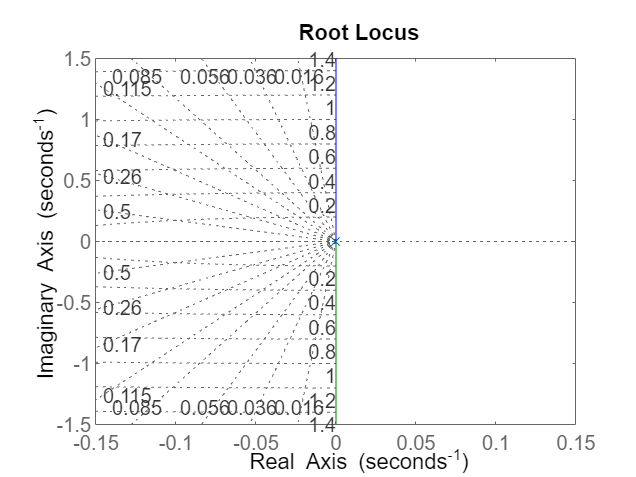

G = 10 / (s^2);   % type 2

### A lead compensator for a type-two system


$$\text{P.O.}\le35\Rightarrow\zeta\ge0.32\\
\text{Pick desired roots }r=-2\pm2j.$$


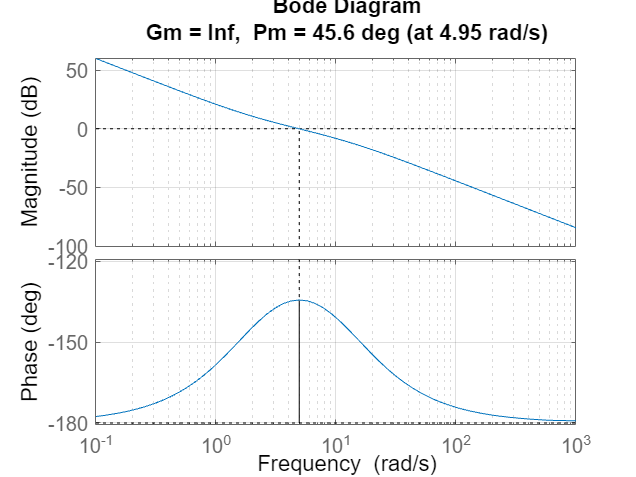

pzratio = 6;
omega_m = 4.95;
p = omega_m * sqrt(pzratio);
z = p / pzratio;
K = pzratio;
G_C = K * (s + z) / (s + p);
L = G_C * G;
T = feedback(L, 1);
margin(L), grid

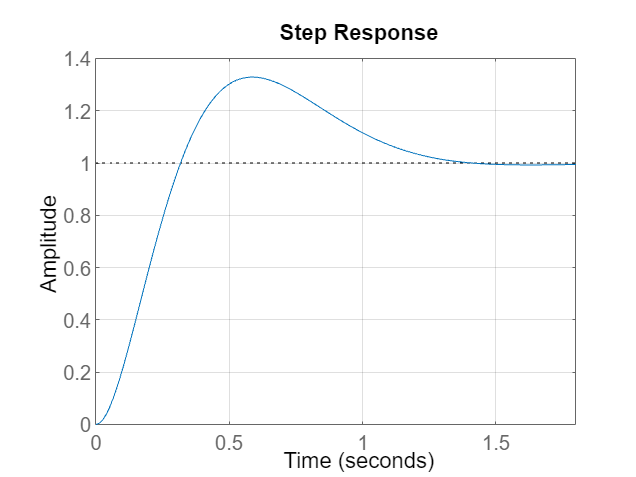

step(T), grid

stepinfo(T)

ans = struct with fields:
         RiseTime: 0.2188
    TransientTime: 1.2657
     SettlingTime: 1.2657
      SettlingMin: 0.9377
      SettlingMax: 1.3289
        Overshoot: 32.8881
       Undershoot: 0
             Peak: 1.3289
         PeakTime: 0.5908


damp(T)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.59e+00 + 3.41e+00i     7.25e-01       4.95e+00         2.79e-01    
 -3.59e+00 - 3.41e+00i     7.25e-01       4.95e+00         2.79e-01    
 -4.95e+00                 1.00e+00       4.95e+00         2.02e-01    
